% This is for 1st JND points  
% 19 distribution candidates in total.
clear all;
close all;
clc;

Evaluation_array = zeros(1,19);
tabulate_array = [];
distribution_model_array_original = ["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma","Kernel",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"];
for x = 1:220
    data_test = my_sample_transform(x,1)';
    distribution_model_array = ["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma","Kernel",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"];
    h_array = zeros(1,length(distribution_model_array));
    p_array = zeros(1,length(distribution_model_array));
    statistic_array = zeros(1,length(distribution_model_array));
    for i = 1:length(distribution_model_array)
        distmodel = fitdist(data_test,distribution_model_array(i));
        [h_array(i), p_array(i), statistic_array(i)]= kstest(...
            data_test,'CDF',distmodel);
        
    end
    
    % This part is meant to first excluded the case whose h-value is 1.
    % Note that we can not use the p-value to judge which approximation is
    % better, but we could use the test statistic to evaluate.
    pos = find(h_array == 1);
    % Delete the element if corresponding h value is 1.
    h_array(pos) = [];
    p_array(pos) = [];
    statistic_array(pos) = [];
    distribution_model_array(pos) = [];
    % Find the model which has the smallest x^2 value.
    [min_x_square_value, pos_index] = min(statistic_array);
    % Find the original index, since maybe some of the position may be
    % excluded during judgment.
    pos_original = find(distribution_model_array_original == distribution_model_array(pos_index));
    % Count the distribution winner for this video.    
    Evaluation_array(pos_original) = Evaluation_array(pos_original) + 1;
    % Concatenate the previous tabulate_array with the distribution winner
    % for this round.
    tabulate_array = [tabulate_array,distribution_model_array_original(pos_original)];
end

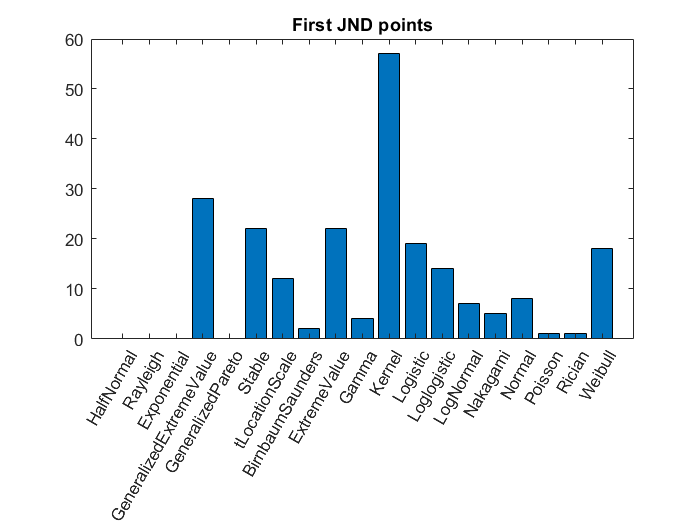

x = 1:19;
bar(x,Evaluation_array);
hold on;
title('First JND points');
xticks(1:19);
xticklabels(["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma","Kernel",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"]);
xtickangle(60);

        tabulate(tabulate_array)

                    Value    Count   Percent
                   Kernel       57     25.91%
             ExtremeValue       22     10.00%
                   Stable       22     10.00%
                  Weibull       18      8.18%
                 Logistic       19      8.64%
                LogNormal        7      3.18%
              Loglogistic       14      6.36%
                   Normal        8      3.64%
  GeneralizedExtremeValue       28     12.73%
           tLocationScale       12      5.45%
         BirnbaumSaunders        2      0.91%
                    Gamma        4      1.82%
                 Nakagami        5      2.27%
                   Rician        1      0.45%
                  Poisson        1      0.45%
